1)Вычислите векторное произведение (x) векторов a [1.3; -3.3; 0.5] 

  и b [4.2; 6.5; -2.7].

a =  [1.3; -3.3; 0.5];
b = [4.2; 6.5; -2.7];
x = cross(a,b)

x =     5.6600
    5.6100
   22.3100


2)Для векторов a и b из п. 1 вычислите axb+bxa. 

a =  [1.3; -3.3; 0.5];
b = [4.2; 6.5; -2.7];
x = cross(a,b)+cross(b,a)

x =      0
     0
     0


3)Даны векторы a [3.5 0.1 0], b [0.5 2.1 0] и c [-0.2 -1.9 2.8].Вычислите смешанное произведение векторов a, b и c.

a = [3.5 0.1 0];
b = [0.5 2.1 0];
c = [-0.2 -1.9 2.8];
x = dot(a, cross(b,c))

x = 20.4400

4) Вычислите внутреннее произведение векторов a, b из п. 3.

a = [3.5 0.1 0];
b = [0.5 2.1 0];
dot(a,b)

ans = 1.9600

5) Найдите объём параллелепипеда, заданного векторами a [1 2 3], b [4 5 6] и c [8 8 8].

a = [1 2 3];
b = [4 5 6];
c = [8 8 8];
x = dot(a, cross(b,c))

x = 0

6) Вычислите внешнее произведение векторов a [1 2 3] и b [4 4 5 5].

a = [1 2 3];
b = [4 4 5 5];
c = b .* a'

c =      4     4     5     5
     8     8    10    10
    12    12    15    15


7) Постройте на одних осях 3 конических сечения, заданных уравнением в полярной системе координат: ρ(1-ɛcosϕ) – a = 0. ɛ = 0.5, потом 1, потом 2, при этом a = 1 во всех 3 случаях. Угол ϕ задайте от –π до π с шагом 0.1*π.

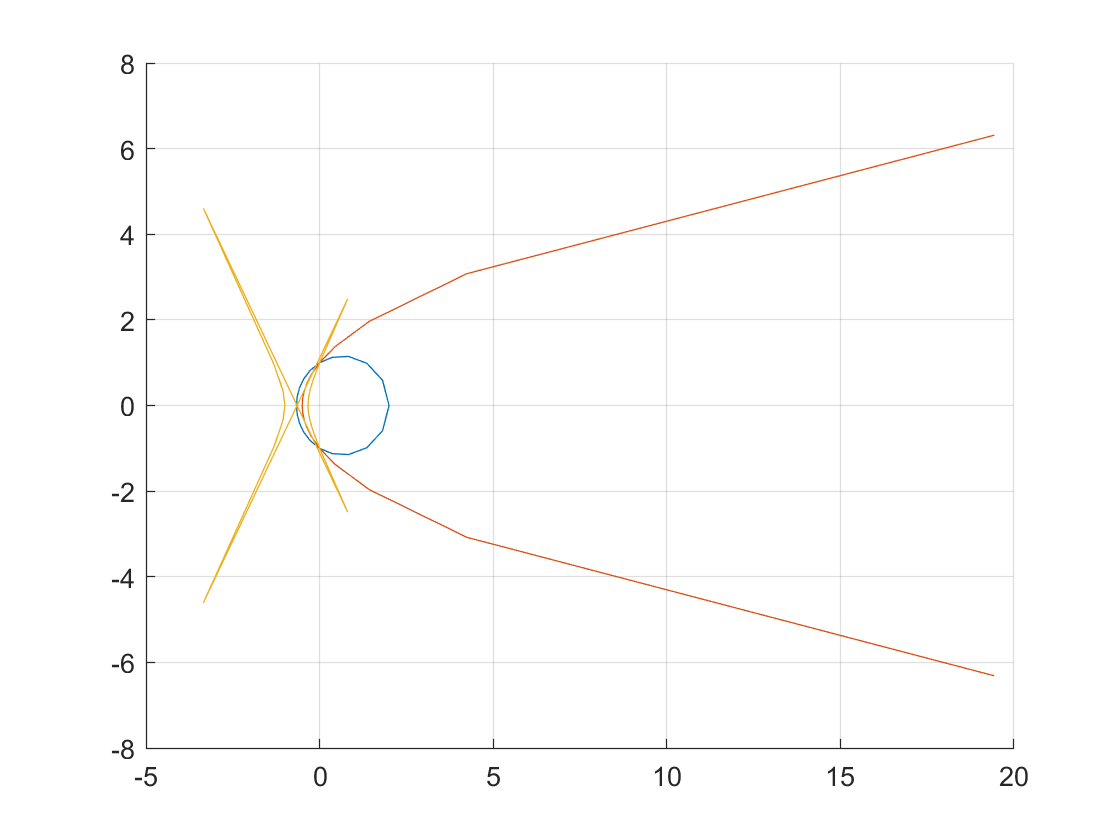

phi = [-pi:0.1*pi:pi];
ep = 0.5;
ro = 1 ./ (1 - ep .* cos(phi));
[x,y] = pol2cart(phi,ro);
figure
grid on
hold on
plot(x,y)
ep = 1;
ro = 1 ./ (1 - ep .* cos(phi));
[x,y] = pol2cart(phi,ro);
plot(x,y)
ep = 2;
ro = 1 ./ (1 - ep .* cos(phi));
[x,y] = pol2cart(phi,ro);
plot(x,y)

8)Постройте так же, как и в п. 7, трёхмерный график (шаг ϕ примите равным 0.05*π), заданный тем же уравнением, считая, что оно задано в цилиндрической системе координат (примите z=ϕ), при этом транспонировав ρ (см. результат на рисунке 1 далее).

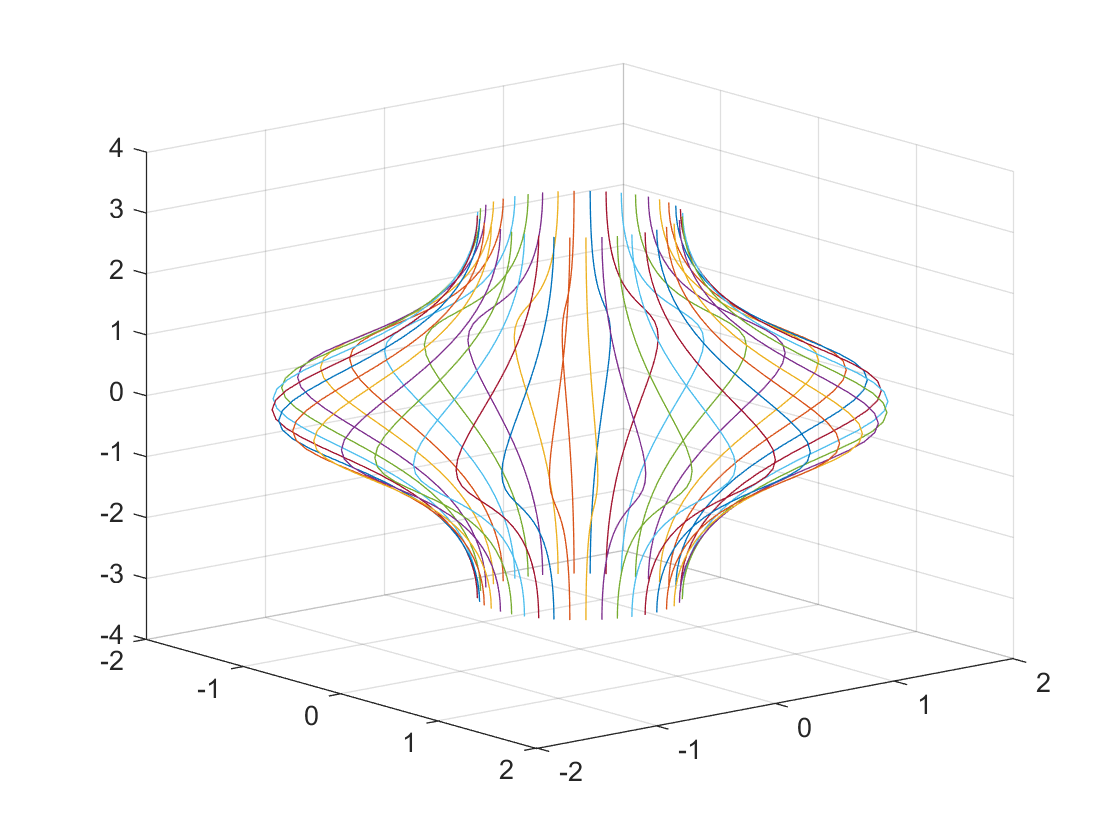

phi = -pi:0.05*pi:pi;
ep = 0.5;
ro = 1 ./ (1 - ep .* cos(phi));
[x,y,z] = pol2cart(phi,ro',phi);
figure
plot3(x,y,z)
view([50.69 16.09])
grid on

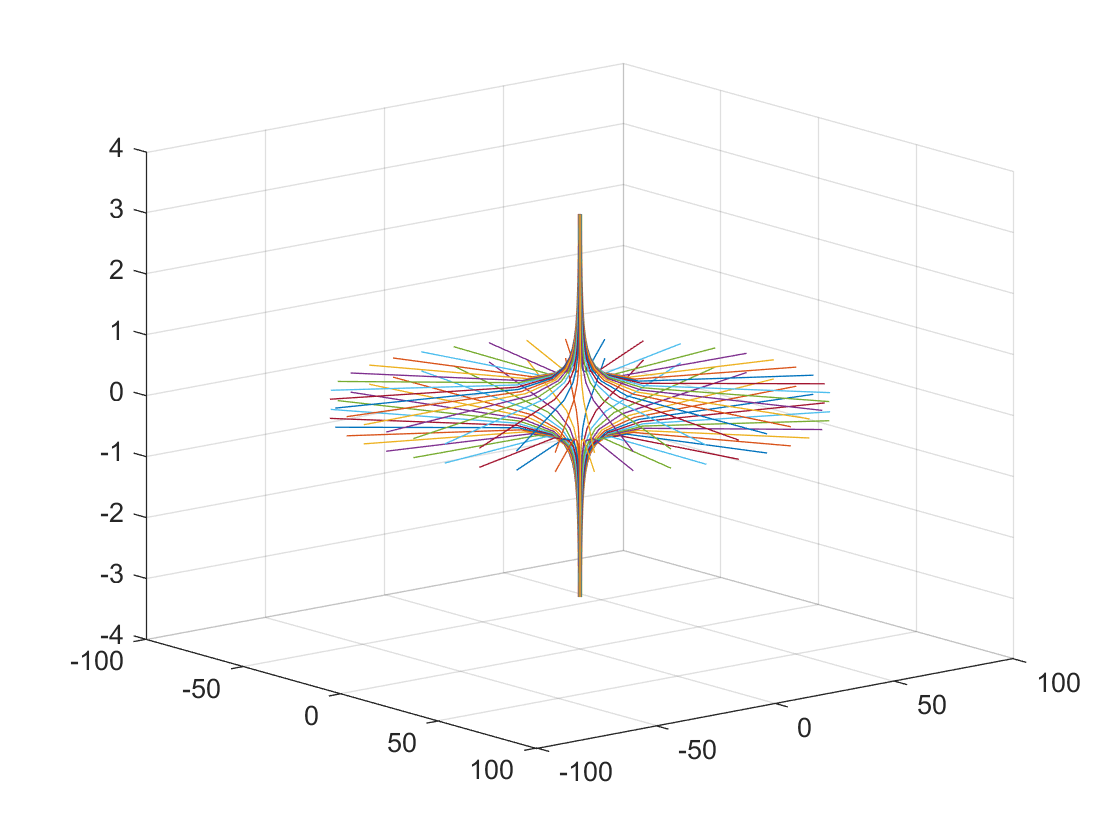

figure
ep = 1;
ro = 1 ./ (1 - ep .* cos(phi));
[x,y,z] = pol2cart(phi,ro',phi);
plot3(x,y,z)
grid on
view([50.69 16.09])

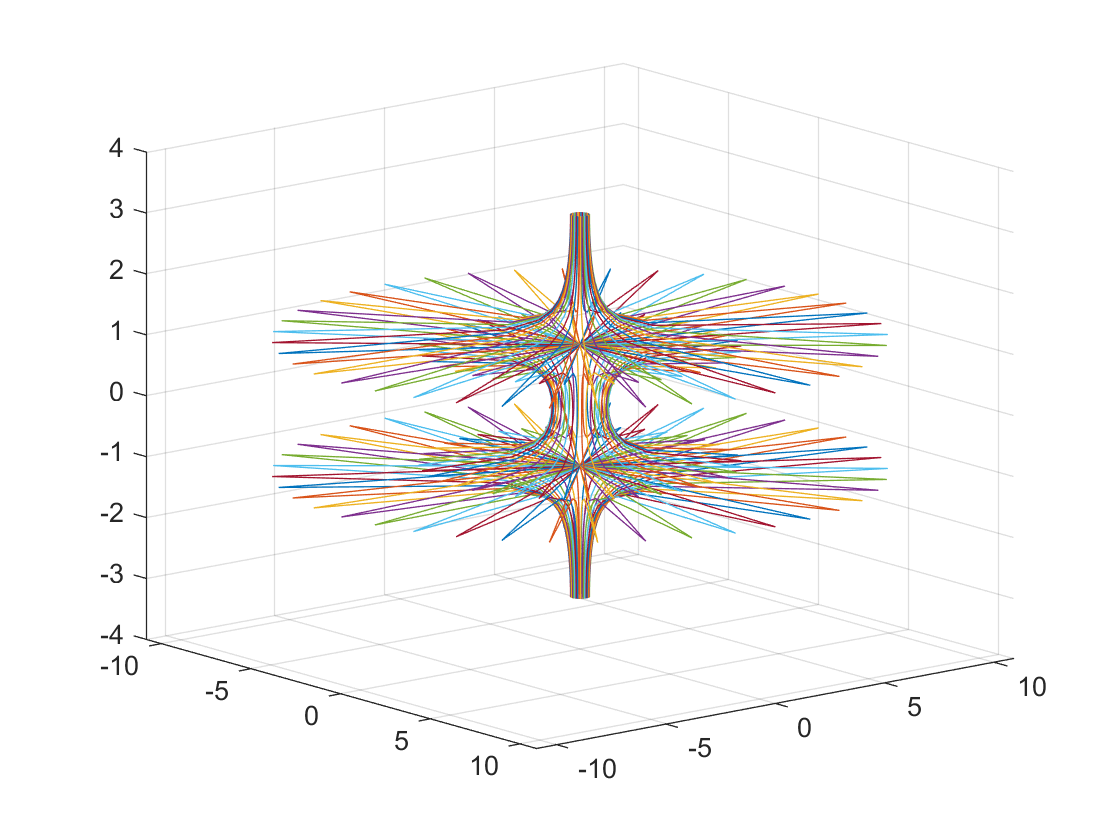

figure
ep = 2;
ro = 1 ./ (1 - ep .* cos(phi));
[x,y,z] = pol2cart(phi,ro',phi);
plot3(x,y,z)
grid on
view([50.69 16.09])

9)Постройте трёхмерный график, заданный уравнением в сферической системе координат: ρ = 1. Угол ϕ задайте от –π до π с шагом 0.01*π(рисунок 2).

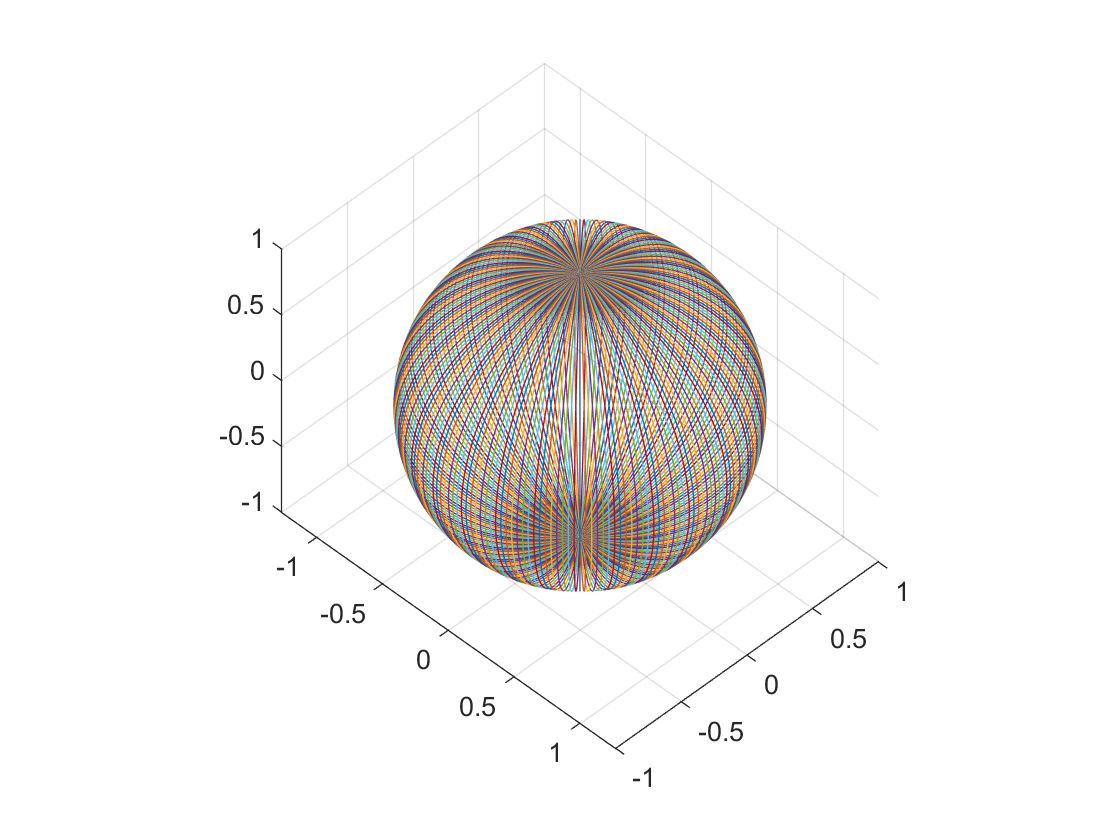

ro = 1;
phi = -pi:0.01*pi:pi;
figure
hold on
grid on
axis equal
[x,y,z] = sph2cart(phi,phi',1);
plot3(x,y,z)
view([45, 45])

10)Превратите ϕ (или что-то другое, надо догадаться) из строки в столбец и проверьте, как изменился график. (рисунок 3).

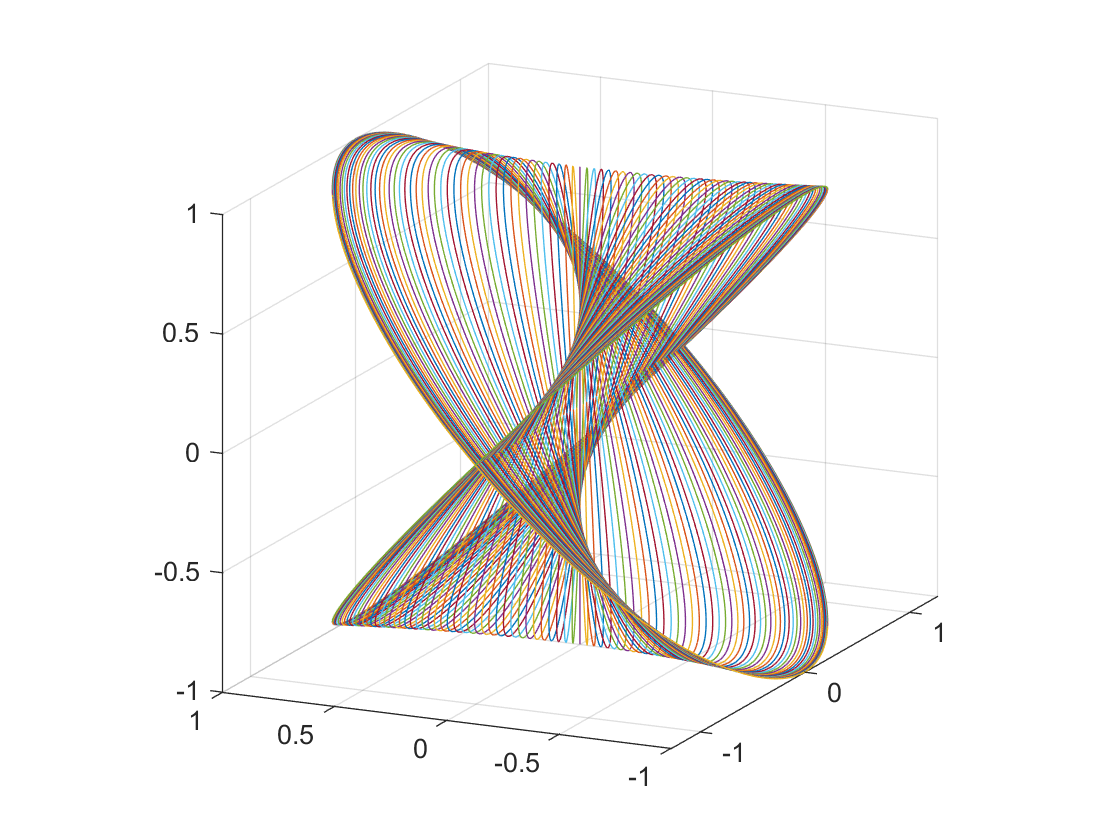

ro = 1;
phi = -pi:0.01*pi:pi;
figure
hold on
grid on
axis equal
[x,y,z] = sph2cart(phi',phi,1);
plot3(x,y,z)
view([-64.98 15.45])